load 3.Fullcoin_Cell11_Formation.mat % load the raw cathode half-cell data  

d = 14.8 % diameter of the cathode in [mm]

d = 14.8000

A = pi*(d/2/10)^2 % surface area of electrode in [cm^2]

A = 1.7203


% t =  % thickness of the electrode coating (do we need this?)
% p =  % porosity of the electrode coating (do we need this?)

x = 1 % set the expansion factor for the cathode in mAh/cm^2.

x = 1

% This is more the target areal capacity for the cathde than the expansion factor though.
% For instance, if target capacity for cathode is set at 1.0 mAh/cm2 and we want
% a full-cell NP ratio of 1.1 then the capacity of the anode will be 1.1 mAh/cm2 


% Plot the experimental and adjusted data for the first cycle
data.cycle_number;  % load the data for cycle number
k = find(data.cycle_number==0 & data.ave_I_mA>0 ); % To find the first discharge
l = find(data.cycle_number==0 & data.ave_I_mA<0); % To find the first charge

Volch = data.Ecell_V(k); % obtain the voltage in the first discharge
Voldch = data.Ecell_V(l); % obtain the voltage in the first charge
Capch = data.Capacity_mAh(k)/A;
Capdch = data.Capacity_mAh(l)/A;
disp('Max capacity on 1st cycle charge and discharge in mAh/cm2')

Max capacity on 1st cycle charge and discharge in mAh/cm2


[MCapch,idxCapch] = max(Capch)

MCapch = 3.3529

idxCapch = 1605

[MCapdch,idxCapdch] = max(Capdch)

MCapdch = 2.7636

idxCapdch = 1190

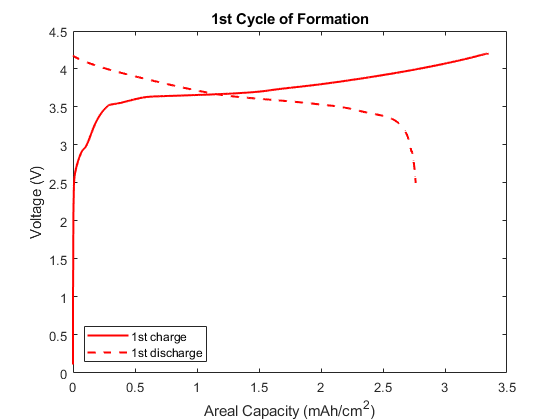

ExpCapch = Capch*x/MCapch; % to obtain the expanded capacity during 1st discharge
ExpCapdch = Capdch*x/MCapch; % to obtain the expanded capacity during 1st charge

plot(Capch,Volch,'r-','linewidth',1.5)
hold on
plot(Capdch,Voldch,'r--','linewidth',1.5)
% plot(ExpCapch,Volch,'b-','linewidth',2) % plot the V vs. capacity(expanded) during during 1st discharge 
% hold on 
% plot(ExpCapdch,Voldch,'b--','linewidth',2) % plot the V vs. capacity(expanded) during during 1st charge 

title('1st Cycle of Formation')
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
legend('1st charge','1st discharge','location',"southwest")
hold off

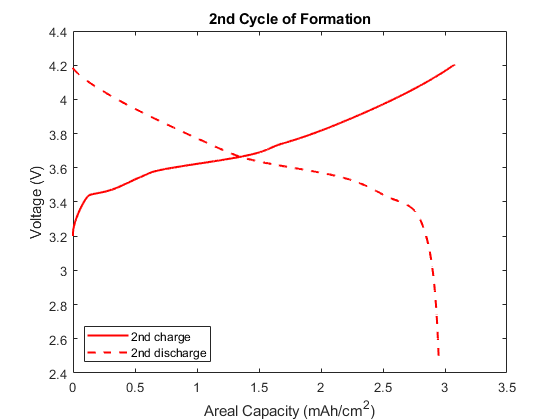


% plot experimental and adjusted data for the second cycle
secondk = find(data.cycle_number==1 & data.ave_I_mA>0 ); % obtain the index for the second discharge
secondl = find(data.cycle_number==1 & data.ave_I_mA<0); % To find the second charge

secondVolch = data.Ecell_V(secondk(2:end)); % obtain the voltage in the second discharge
secondVoldch = data.Ecell_V(secondl); % obtain the voltage in the second charge
secondCapch = data.Capacity_mAh(secondk(2:end))/A;
secondCapdch = data.Capacity_mAh(secondl)/A;
[M2ndCapch,idx2ndCapch] = max(secondCapch);
[M2ndCapdch,idx2ndCapdch] = max(secondCapdch);
ExpCap2ndch = secondCapch*x/MCapdch; % to obtain the expanded capacity during 2nd discharge
ExpCap2nddch = secondCapdch*x/MCapdch; % to obtain the expanded capacity during 2nd charge

plot(secondCapch,secondVolch,'r-','linewidth',1.5)
hold on
plot(secondCapdch,secondVoldch,'r--','linewidth',1.5)
% plot(ExpCap2ndch,secondVolch,'b-','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd discharge
% plot(ExpCap2nddch,secondVoldch,'b--','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd charge

title('2nd Cycle of Formation')
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
legend('2nd charge','2nd discharge','location',"southwest")
hold off


% To make a comparision between real and calculated voltage for half cell and full cell
% To use the first cycle
disp('The comparision of calculated voltage and real voltage for full cell')

The comparision of calculated voltage and real voltage for full cell


Vch_1st=min(Volch)%

Vch_1st = 0.1123

Vdch_1st=max(Voldch)%

Vdch_1st = 4.1783

s1= C_Vxpch-A_Vxpdch

s1 =     0.1938
    2.8209
    2.9889
    3.0456
    3.1395
    3.2409
    3.3195
    3.3802
    3.4288
    3.4691


for i1=1:size(s1)
    if abs(s1(i1)-Vch_1st)<0.1
        j1=i1
    end
end

j1 = 1

O1=C_Vxpdch-A_Vxpch

O1 =        NaN
    4.1905
    4.1682
    4.1461
    4.1265
    4.1087
    4.0929
    4.0780
    4.0636
    4.0500


for k1=1:size(O1)
    if abs(O1(k1)-Vdch_1st)<0.012
        l1=k1
    end
end

l1 = 3


for r1=1:size(s1)
    if abs(s1(r1)-4.2)<0.015 & s1(r1)-4.2 >0
        p1=r1
    end
end

p1 = 95

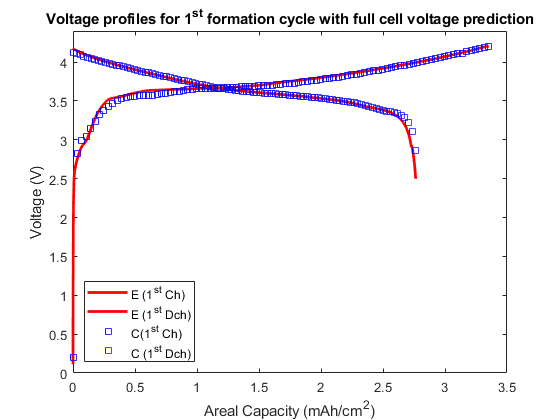

 
plot(Capch,Volch,'r-','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd charge
hold on
plot(Capdch,Voldch,'r-','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd discharge
scatter ((C1_m(j1:p1)-C1_m(j1))*C1_m(end)/C1_m(p1)*MCapch,s1(j1:p1),'bs','MarkerEdgeAlpha', 0.8);
scatter((C1_n(5:end-1)-C1_n(5))*MCapdch/max(C1_n(end-5)),O1(5:end-1),'bs', 'MarkerEdgeAlpha', 0.7);

xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
title('Voltage profiles for 1^s^t formation cycle with full cell voltage prediction')
legend('E (1^s^t Ch)','E (1^s^t Dch)','C(1^s^t Ch)','C (1^s^t Dch)','location',"southwest")
hold off
% set(gca,'color',[0.5 0.5 0.5])
xlim([0 3.5])
ylim([0.0 4.4])




CV_max=max(C_Vxp2ndch-A_Vxp2nddch)

CV_max = 4.2951



% To use the second cycle
disp('The comparision of calculated voltage and real voltage for full cell')

The comparision of calculated voltage and real voltage for full cell


Vch_1st=min(secondVolch)%

Vch_1st = 3.2014

Vdch_1st=max(secondVoldch)%

Vdch_1st = 4.1850

s= C_Vxp2ndch-A_Vxp2nddch

s =     2.4024
    2.8427
    3.0413
    3.1609
    3.2458
    3.3113
    3.3641
    3.4073
    3.4399
    3.4494


for i=1:size(s)
    if abs(s(i)-Vch_1st)<0.05
        j=i
    end
end

j = 4

j = 5

O=C_Vxp2nddch-A_Vxp2ndch

O =     4.2488
    4.2012
    4.1788
    4.1555
    4.1352
    4.1172
    4.1007
    4.0854
    4.0709
    4.0568


for k=1:size(O)
    if abs(O(k)-Vdch_1st)<0.01
        l=k
    end
end

l = 3


for r=1:size(s)
    if abs(s(r)-4.2)<0.02 & s(r)-4.2>0
        p=r
    end
end

p = 96

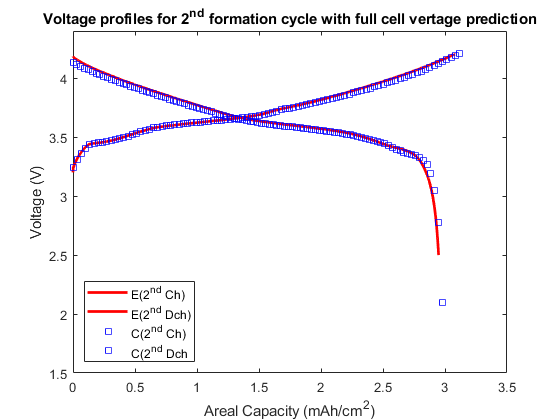

 
plot(secondCapch,secondVolch,'r-','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd charge
hold on
plot(secondCapdch,secondVoldch,'r-','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd discharge
scatter ((C2_m(j:p)-A2_m(j))*C2_m(end)/C2_m(p-j)*(M2ndCapch),s(j:p),'bs', 'MarkerEdgeAlpha', 0.7);
scatter((C2_n(5:end)-C2_n(5))*M2ndCapdch/max(C2_n(end-5)),O(5:end),'bs', 'MarkerEdgeAlpha', 0.7);

xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
title('Voltage profiles for 2^n^d formation cycle with full cell vertage prediction')
legend('E(2^n^d Ch)','E(2^n^d Dch)','C(2^n^d Ch)','C(2^n^d Dch','location',"southwest")
hold off
% set(gca,'color',[0.5 0.5 0.5])
xlim([0 3.5])
ylim([1.06 4.4])

xlim([0.00 3.50])
ylim([1.5 4.40])


CV_max=max(C_Vxp2ndch-A_Vxp2nddch)

CV_max = 4.2951


% create data for prediction full cell voltage for full cells from half cells
V_s_1ch=[C_Vxpch(j1),A_Vxpdch(j1),min(Volch)];
V_e_1ch=[C_Vxpch(p1),A_Vxpdch(p1),max(Volch)];
V_s_1dch=[C_Vxpdch(l1),A_Vxpch(l1),max(Voldch)];
V_e_1dch=[C_Vxpdch(end-1),A_Vxpch(end-1),min(Voldch)];
Voltage_1st={'Voltage/v';'start of 1ch';'end of 1ch';'start of 1dch';'end of 1dch'};
Data_Vpredict_1st=[V_s_1ch;V_e_1ch;V_s_1dch;V_e_1dch];
Header_Data_Vpredict_1st = {'Cathode/ V','Anode/V','full cell/V'};
Data_Vpredict_1st=[Header_Data_Vpredict_1st ;num2cell(Data_Vpredict_1st )];
Data_Vpredict_1st=[Voltage_1st,Data_Vpredict_1st];

% create data for prediction full cell voltage for full cells from half cells
% for the second cycle
V_s_2ch=[C_Vxp2ndch(j),A_Vxp2nddch(j),min(secondVolch)];
V_e_2ch=[C_Vxp2ndch(p),A_Vxp2nddch(p1),max(secondVolch)];
V_s_2dch=[C_Vxp2nddch(l),A_Vxp2ndch(l),max(secondVoldch)];
V_e_2dch=[C_Vxp2nddch(end-1),A_Vxp2ndch(end-1),min(secondVoldch)];
Voltage_2st={'Voltage/v';'start of 1ch';'end of 1ch';'start of 1dch';'end of 1dch'};
Data_Vpredict_2st=[V_s_2ch;V_e_2ch;V_s_2dch;V_e_2dch];
Header_Data_Vpredict_2st = {'Cathode/ V','Anode/V','full cell/V'};
Data_Vpredict_2st=[Header_Data_Vpredict_2st ;num2cell(Data_Vpredict_2st )];
Data_Vpredict_2st=[Voltage_2st,Data_Vpredict_2st];

% To use the second cycle
disp('The comparision of calculated voltage and real voltage for full cell')

The comparision of calculated voltage and real voltage for full cell


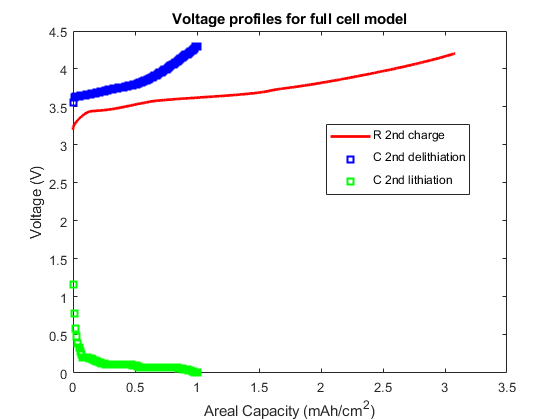

plot(secondCapch,secondVolch,'r-','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd charge
hold on
% plot(secondCapdch,secondVoldch,'r--','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd discharge
plot(C2_m,C_Vxp2ndch,'bs','linewidth',2);
plot(C2_m, A_Vxp2nddch,'gs','linewidth',2);
% plot(C_n,C_Vxp2nddch,C_m,A_Vxp2ndch,'b--','linewidth',2);

xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
title('Voltage profiles for full cell model')
legend('R_ 2nd charge','C_ 2nd delithiation','C_ 2nd lithiation','location',"best")
hold off


% To use the second cycle
disp('The comparision of calculated voltage and real voltage for full cell')

The comparision of calculated voltage and real voltage for full cell


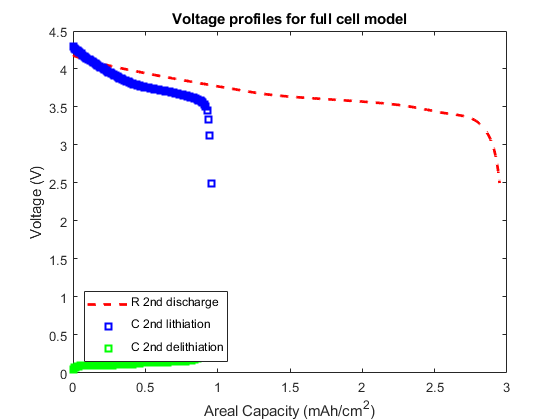

% plot(secondCapch,secondVolch,'r-','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd charge
% hold on
plot(secondCapdch,secondVoldch,'r--','linewidth',2) % plot the V vs. capacity(expanded) during during 2nd discharge
%plot(C_m,C_Vxp2ndch,C_m, A_Vxp2nddch,'b-','linewidth',2);
hold on
plot(C2_n,C_Vxp2nddch,'bs','linewidth',2);
plot(C2_m,A_Vxp2ndch,'gs','linewidth',2);
xlabel('Areal Capacity (mAh/cm^2)')
ylabel('Voltage (V)')
title('Voltage profiles for full cell model')
legend('R_ 2nd discharge','C_ 2nd lithiation','C_ 2nd delithiation','location',"southwest")
hold off

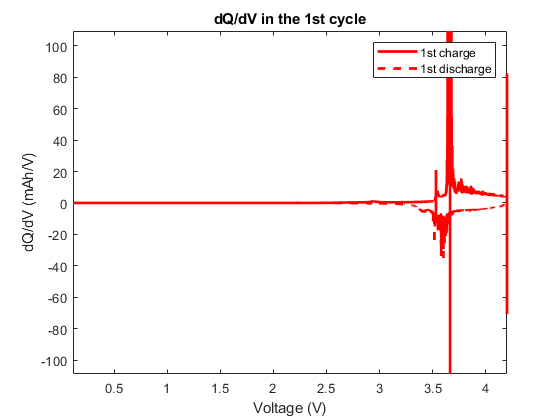


% To calcualte the dQ/dV for the 1st and 2nd cycles
% To use the factor to plot the voltage dQ/dV vs. dV
%To calculate dV and dQ in the first cycle
% To obtain the first discharge
m = 1:(size(Volch)-1);
deltaVmch = Volch(m+1)-Volch(m);
deltaCapmch = 1.7203*x*(Capch(m+1)-Capch(m));
DiffQVch = deltaCapmch./deltaVmch;
plot(Volch(1:end-1),DiffQVch,'r-','linewidth',2)
set(gca,'xDir','normal')
hold on

n = 1:(size(Voldch)-1);
deltaVmdch = Voldch(n+1)-Voldch(n);
deltaCapmdch = 1.7203*x*(Capdch(n+1)-Capdch(n));
% To plot the dQ/dV in the first cycle
plot(Voldch(2:end),deltaCapmdch./deltaVmdch,'r--','linewidth',2);

xlabel('Voltage (V)')
ylabel('dQ/dV (mAh/V)')
legend('1st charge','1st discharge')
title('dQ/dV in the 1st cycle')
hold off
axis tight


% To calculate dV and dQ in the second cycle
%Function for DVA and ICA to make the data smooth

MA = 25;  % span for moving average filter

% g = gausswin(100);  % 100 is the sample size for the gaussian window

% g value determines the width of the smoothing window.
%  If you have signal process toolbox uncomment above else use the expressions below, 

%%%%%%%%%%%%%%%%%%%%%%%% Use this fitted gausswin if you don't have signal processing
%%%%%%%%%%%%%%%%%%%%%%%% toolbox. Here using the fitted value
%  of gausswin for 100 sample size, for different sample size, fit and
%  change the value of alpha.

N=100;
M= (N-1)/2;
alpha=2.5;
n= (-(N-1)/2:(N-1)/2)';
g= exp((-0.5)*((alpha^2 *n.^2)/(M^2)));
g = g/sum(g);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%
B = 1:(size(secondVolch)-1);
deltaVm2ndch = secondVolch(B+1)-secondVolch(B);
deltaCapm2ndch = A*x*(secondCapch(B+1)-secondCapch(B));
DiffQV2ndch = deltaCapm2ndch./deltaVm2ndch;
A1 =plot(secondVolch(1:end-1),smooth(DiffQV2ndch),'b-','linewidth',2)

A1 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×1243 double]
              YData: [1×1243 double]
              ZData: [1×0 double]

  Show all properties


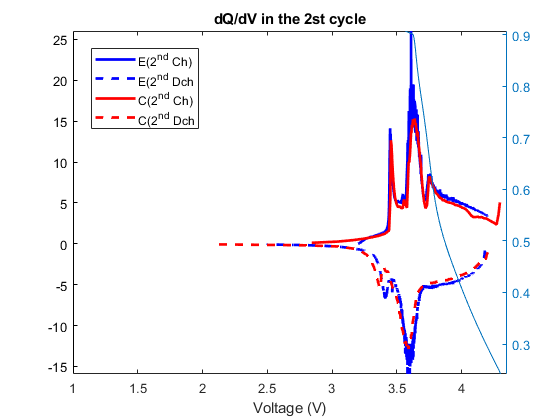

A1.Color(4) = 0.9;
set(gca,'xDir','normal')
hold on
% To obtain the first discharge
C = 1:(size(secondVoldch)-1);
deltaVm2nddch = secondVoldch(C+1)-secondVoldch(C);
deltaCapm2nddch = A*x*(secondCapdch(C+1)-secondCapdch(C));
% To plot the dQ/dV in the first cycle
A2=plot(secondVoldch(2:end),smooth(deltaCapm2nddch)./smooth(deltaVm2nddch),'b--','linewidth',2);
plot(s(2:end),A*M2ndCapch*diff(C2_m)./diff(s),'r-','linewidth',2)
plot(O(2:end),A*M2ndCapdch*diff(C2_n)./diff(O),'r--','linewidth',2)
yyaxis right
plot(C_Vxp2ndch,Sc_Vxp2ndch)
xlabel('Voltage (V)')
ylabel('dQ/dV (mAh/V)')
legend('E(2^n^d Ch)','E(2^n^d Dch','C(2^n^d Ch)','C(2^n^d Dch','Location',"best")
title('dQ/dV in the 2st cycle')
axis tight
xlim([1.00 4.35])
ylim([0.232 0.964])
hold off


% To put the dQ/dV for the 1st and 2nd cycles
plot(Volch(1:end-1),DiffQVch,'r-','linewidth',2)

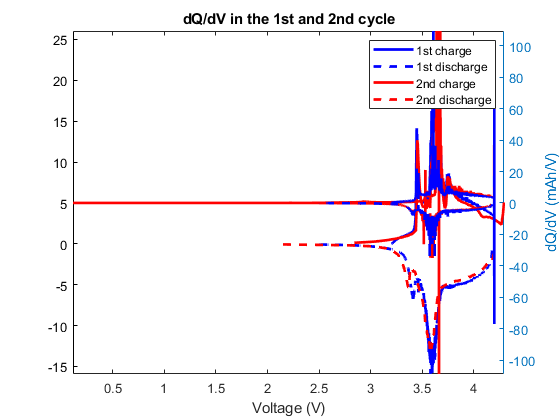

hold on
plot(Voldch(2:end),deltaCapmdch./deltaVmdch,'r-','linewidth',2)
plot(secondVolch(1:end-1),DiffQV2ndch,'b-','linewidth',2)
plot(secondVoldch(2:end),deltaCapm2nddch./deltaVm2nddch,'b--','linewidth',2)
xlabel('Voltage (V)')
ylabel('dQ/dV (mAh/V)')
legend('1st charge','1st discharge','2nd charge','2nd discharge')
title('dQ/dV in the 1st and 2nd cycle')
hold off
axis tight